midiData = readmidi('example.midi')

pianoRoll = midi2hz(midiData); %convert midi data to piano roll

%visualize the piano roll
imagesc(pianoRoll);
xlabel('Time Steps');
ylabel('MIDI Note Number');
title('Piano Roll Representation');

%normalize the velocity values between 0 and 1
pianoRoll = pianoRoll / max(pianoRoll(:));

%sequence length
sequenceLength = 100;

%padding sequences to the same length
pianoRollPadded = padarray(pianoRoll, [0, sequenceLength - size(pianoRoll, 2)], 0, 'post');

[m, n] = size(pianoRollPadded); % m = number of MIDI notes, n = number of time steps
disp([m, n]); % Display dimensions


% Define the number of sequences
totalLength = size(pianoRollPadded, 2);
numSequences = totalLength - sequenceLength + 1;

if numSequences <= 0
    error('the sequence length is too large for the given data');
end

% Define the LSTM network architecture
layers = [
    sequenceInputLayer(size(pianoRoll, 1))    % Input size: number of MIDI notes
    lstmLayer(128, 'OutputMode', 'sequence')  % First LSTM layer with 128 hidden units
    lstmLayer(128, 'OutputMode', 'sequence')  % Second LSTM layer
    fullyConnectedLayer(size(pianoRoll, 1))   % Fully connected layer to output note probabilities
    softmaxLayer                             % Softmax activation for note probability
    regressionLayer                          % Regression layer to predict continuous values (note velocities)
];

% Define training options
options = trainingOptions('adam', ...
    'MaxEpochs', 100, ...                     % Number of epochs
    'MiniBatchSize', 64, ...                  % Batch size
    'InitialLearnRate', 0.001, ...            % Learning rate
    'Shuffle', 'every-epoch', ...             % Shuffle data every epoch
    'Plots', 'training-progress', ...         % Plot training progress
    'Verbose', false);                        % Suppress verbose output

% Prepare the data in the format required by the LSTM
XTrain = {};
YTrain = {};

for i = 1:numSequences
    % Select a starting point for the sequence
    idx = i;
    
    % Ensure indices do not exceed bounds
    if idx + sequenceLength - 1 > size(pianoRollPadded, 2)
        break;
    end
    
    % Extract input (X) and target (Y) sequences
    XTrain{i} = pianoRollPadded(:, idx:idx+sequenceLength-1);
    if idx + sequenceLength <= size(pianoRollPadded, 2)
        YTrain{i} = pianoRollPadded(:, idx+1:idx+sequenceLength); % Target is shifted by one timestep
    else
        % Handle edge case when `YTrain` sequence would exceed bounds
        YTrain{i} = [pianoRollPadded(:, idx+1:end), zeros(m, idx + sequenceLength - size(pianoRollPadded, 2))];
    end
end


% Train the LSTM network
net = trainNetwork(XTrain, YTrain, layers, options);

% Read MIDI data
midiData = readmidi('example.midi');

% Convert MIDI data to piano roll representation
pianoRoll = midi2hz(midiData);

% Visualize the piano roll
imagesc(pianoRoll);
xlabel('Time Steps');
ylabel('MIDI Note Number');
title('Piano Roll Representation');

% Normalize the velocity values between 0 and 1
pianoRoll = pianoRoll / max(pianoRoll(:));

% Define sequence length
sequenceLength = 100;

% Get dimensions of piano roll
[m, n] = size(pianoRoll); % m = number of MIDI notes, n = number of time steps

% Check if sequence length is feasible and pad if necessary
if sequenceLength > n
    % Pad the piano roll with zeros to make it longer
    pianoRollPadded = padarray(pianoRoll, [0, max(0, sequenceLength - n)], 0, 'post');
else
    pianoRollPadded = pianoRoll;
end

% Update dimensions after padding
[m, n] = size(pianoRollPadded); % Updated dimensions
disp(['Number of MIDI notes: ', num2str(m)]);
disp(['Number of time steps (after padding): ', num2str(n)]);

% Define the number of sequences
totalLength = size(pianoRollPadded, 2);
numSequences = totalLength - sequenceLength + 1;

if numSequences <= 0
    error('The sequence length is too large for the given data after padding.');
end

% Define the LSTM network architecture
layers = [
    sequenceInputLayer(size(pianoRoll, 1))    % Input size: number of MIDI notes
    lstmLayer(128, 'OutputMode', 'sequence')  % First LSTM layer with 128 hidden units
    lstmLayer(128, 'OutputMode', 'sequence')  % Second LSTM layer
    fullyConnectedLayer(size(pianoRoll, 1))   % Fully connected layer to output note probabilities
    softmaxLayer                             % Softmax activation for note probability
    regressionLayer                          % Regression layer to predict continuous values (note velocities)
];

% Define training options
options = trainingOptions('adam', ...
    'MaxEpochs', 100, ...                     % Number of epochs
    'MiniBatchSize', 64, ...                  % Batch size
    'InitialLearnRate', 0.001, ...            % Learning rate
    'Shuffle', 'every-epoch', ...             % Shuffle data every epoch
    'Plots', 'training-progress', ...         % Plot training progress
    'Verbose', false);                        % Suppress verbose output

% Prepare the data in the format required by the LSTM
XTrain = cell(numSequences, 1);
YTrain = cell(numSequences, 1);

for i = 1:numSequences
    % Select a starting point for the sequence
    idx = i;

    % Extract input (X) and target (Y) sequences
    XTrain{i} = pianoRollPadded(:, idx:idx+sequenceLength-1);
    YTrain{i} = pianoRollPadded(:, idx+1:idx+sequenceLength); % Target is shifted by one timestep
end

% Train the LSTM network
net = trainNetwork(XTrain, YTrain, layers, options);

%TRIAL 2
% reading midi files
% we are using the MIDI toolbox (readmdi function)
% this code is designed to read a midi file, preprocess its musical notes,
% train an LSTM to predict the next note in a sequence, and generate a new
% sequence of notes. the generated sequence is then saved as a new midi
% file which is played back as audio
midiData = readmidi("D:\TANVI_COLLEGE_FILES\ESMT_PROJECT_SEM5\maestro-v3.0.0-midi\maestro-v3.0.0\2004\example.midi")
notes = midiData.notes; % extract note information

% data preprocessing
noteSequences = notes(:, 3); % extract midi numbers
seqLength = 50;

inputs = [];
targets = [];

for i = 1:(length(noteSequences) - seqLength)
    inputSeq = noteSequences(i:i + seqLength - 1); 
    targetNote = noteSequences(i + seqLength); 
    inputs = [inputs; inputSeq'];
    targets = [targets; targetNote];
end

disp(inputs(1:5, :));
disp(targets(1:5, :));

% define network architecture
inputSize = numUniqueNotes;
numHiddenUnits = 128;
numClasses = numUniqueNotes;
layers = [ ...
    sequenceInputLayer(inputSize), ...
    lstmLayer(numHiddenUnits, 'OutputMode', 'last'), ...
    fullyConnectedLayer(numClasses), ...
    softmaxLayer, ...
    classificationLayer];

% Display network layers
%disp(layers);

% prepare data for training
XTrain = num2cell(inputVectors, [1 2]);
YTrain = categorical(targets);

net = trainNetwork(Xtrain, YTrain, layers, options);

seedSequence = inputs(1, :);
numGeneratedNotes = 200;
generatedSequence= seedSequence;
for i = 1:numGeneratedNotes
    inputSeq = zeros(seqLength,  numUniqueNotes);
    for j = 1:sequenceLength
        noteIndex = find(unieqNotes == generatedSequence(end - seq+j));
        inputSeq(j, noteIndex) = 1;
    end
    netInput = reshape(inputSeq, [sequenceLength, numUniqueNotes, 1]);
    predictedProb = predict(net, netInput);
    [~, idx] = max(predictedProb);
    nextNote = uniqueNotes(idx)
    generatedSequence = [generatedSequence; nextNote];
end

%create midi structure
midiNew = matrix2midi([zeros(length(generatedSequence), 1), ...
    ones(length(generatedSequence), 1), ...
    generatedSequence]);
writemidi(midiNew, 'generated_music.mid');

% read and play midi file
[y, fs] = audioread('generated_music.midi');
sound(y, fs)

% PROJECT TRIAL 3

% Loading a MIDI file into MATLAB
%midiFile = 'D:\TANVI_COLLEGE_FILES\ESMT_PROJECT_SEM5\maestro-v3.0.0-midi\maestro-v3.0.0\2004\example.midi';

%midiData = readmidi(midiFile)

% extract notes information
%noteMatrix = midiInfo(midiData, 0); % not working

% preprocessing midi data
% convert midi information into a format suitable for input into an LSTM
% network

% first convert into piano roll which is a common representation where rows
% represent MIDI note numbers (0-127), the columns represent time steps and
% the values represent note velocities


% using WAV file
%wavFile = "D:\TANVI_COLLEGE_FILES\ESMT_PROJECT_SEM5\maestro-v3.0.0-midi\maestro-v3.0.0\2004\example.wav";
%[y, Fs] = audioread(wavFile); % read wav file
%player = audioplayer(y, Fs);
%play(player);
%stop(player);
%pause(player);
%resume(player);

[wavData, Fs] = audioread("D:\TANVI_COLLEGE_FILES\ESMT_PROJECT_SEM5\maestro-v3.0.0-midi\maestro-v3.0.0\2004\example.wav");

% checks if the wavData has two columns, which indicates stereo audio
if size(wavData, 2) == 2
    wavData = mean(wavData, 2);
end

window = hamming(2048);
overlap = 512;

[S, F, T] = spectrogram(wavData, window, overlap, [], Fs);
%figure;
%imagesc(T, F, 10*log10(abs(S)));
%axis xy;
%xlabel('Time (s)');
%ylabel('Frequency (Hz)');
%title('Spectrogram');
%colorbar;

S_norm = abs(S) / max(abs(S(:)))

S_norm =     0.0008    0.0000    0.0000    0.0004    0.0007    0.0042    0.0010    0.0003    0.0012    0.0007    0.0026    0.0011    0.0005    0.0003    0.0027    0.0012    0.0045    0.0001    0.0011    0.0012    0.0008    0.0051    0.0038    0.0034    0.0012    0.0024    0.0056    0.0033    0.0106    0.0027    0.0058    0.0033    0.0027    0.0035    0.0063    0.0034    0.0050    0.0050    0.0048    0.0058    0.0051    0.0033    0.0043    0.0030    0.0049    0.0026    0.0029    0.0032    0.0068    0.0011
    0.0012    0.0005    0.0005    0.0001    0.0003    0.0067    0.0006    0.0012    0.0006    0.0006    0.0006    0.0001    0.0002    0.0010    0.0011    0.0010    0.0024    0.0019    0.0018    0.0009    0.0036    0.0011    0.0004    0.0010    0.0034    0.0013    0.0005    0.0014    0.0036    0.0018    0.0024    0.0005    0.0035    0.0022    0.0009    0.0026    0.0027    0.0021    0.0030    0.0021    0.0021    0.0035    0.0022    0.0028    0.0010    0.0024    0.0008    0.0023    0.0015

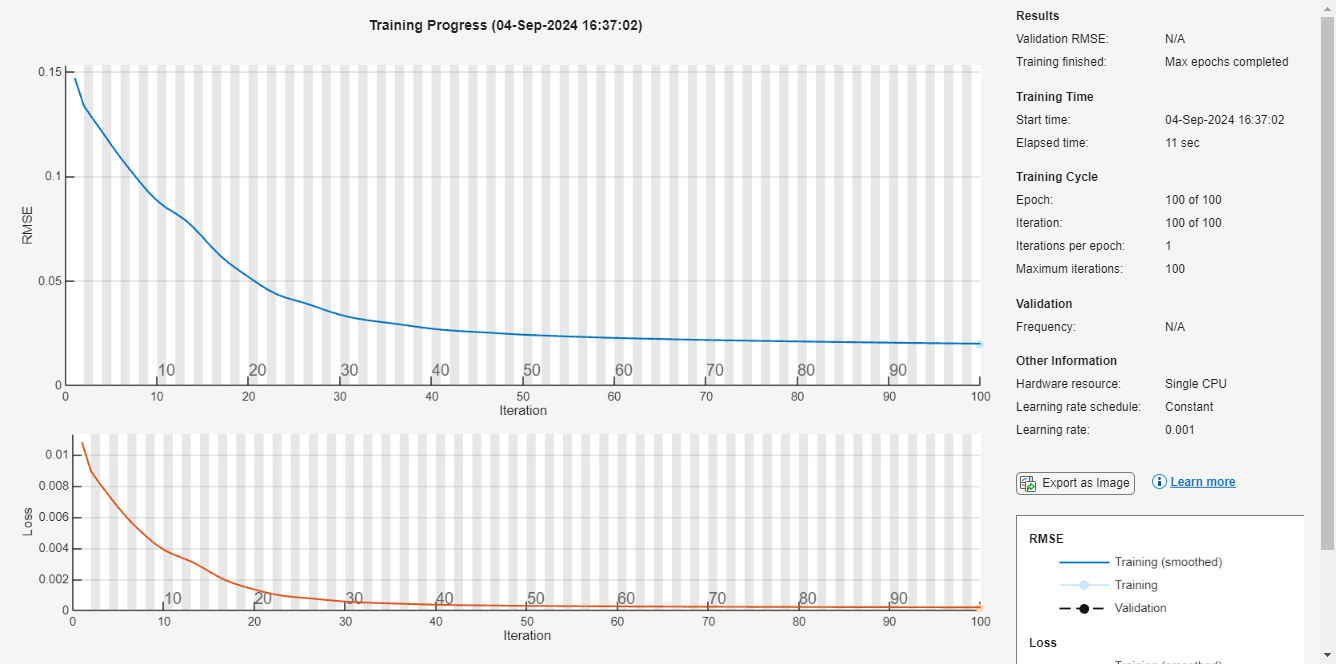

sequenceLength = 100;
XTrain = {};
YTrain = {};

for i = 1:(size(S_norm, 2)-sequenceLength)
    XTrain{1} = S_norm(:, i:i + sequenceLength-1); % input sequence
    YTrain{1} = S_norm(:, i+1:i+sequenceLength); % target sequence
end

inputSize = size(S_norm, 1);
numHiddenUnits = 128;

layers = [sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits, 'OutputMode', 'sequence')
    fullyConnectedLayer(inputSize)
    regressionLayer];

% train the model
options = trainingOptions('adam', ...
    'MaxEpochs', 100, ...
    'MiniBatchSize', 64, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', false, ...
    'Plots', 'training-progress');
net = trainNetwork(XTrain, YTrain, layers, options);


%generate new music
generatedSequence = XTrain{1}; % start with the first input sequence

Brace indexing is not supported for variables of this type.

numGeneratedSteps = 100;
for i = 1:numGeneratedSteps
    newSequence = predict(net, generatedSequence);
    generatedSequence = [generatedSequence(:, 2:end), newSequence(:, end)];
end

%generated sequence back to waveform
generatedWav = istft(generatedSequence, Fs, 'Window', 'window', 'OverlapLength', overlap);
audiowrite('generatedMusic.wav', generatedWav, Fs); % save the generated music as a new wav file

player = audioplayer(generatedWav, Fs);
play(player);

